Some experiments to better understand residual analysis

clear;
load('processed_thruster_data.mat');
models = load('models.mat');


M = models.M_tfest;

data = data_square_unfiltered;
time = time_square

time =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580    0.0600    0.0620    0.0640    0.0660    0.0680    0.0700    0.0720    0.0740    0.0760    0.0780    0.0800    0.0820    0.0840    0.0860    0.0880    0.0900    0.0920    0.0940    0.0960    0.0980


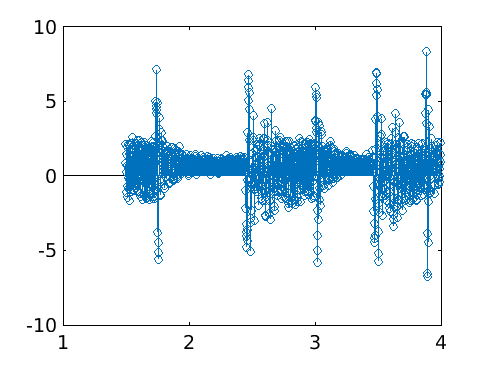


y_estimated = lsim(M, data.u, time);
residuals = data.y - y_estimated;
I = (1.5/Ts):(4/Ts);
stem(time(I), residuals(I));

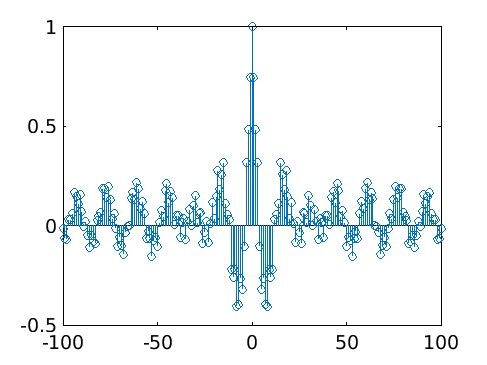

[c,lags] = xcorr(residuals, 100, 'normalized');
stem(lags,c)

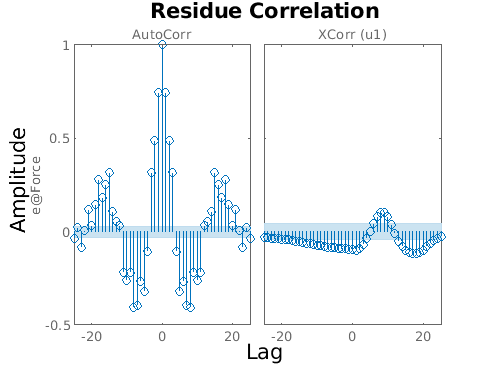


resid(M, data);

Some tests to understand cross- and auto-correlation better

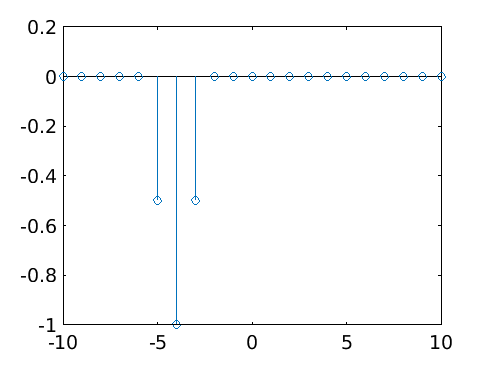

% test example:
a = [0 0 0 1 1 0 0 0 0 0 0];
b = [0 0 0 0 0 0 0 -1 -1 0 0];
[c, lags] = xcorr(a, b, 'normalized');
stem(lags, c)

% cross correlation is negative because shift AND mirroring is necessary

[c, lags] = xcorr([1 1 -1 -1 0 0 1 1 -1 -1 0 0], 'normalized')

c =    -0.0000   -0.0000   -0.1250   -0.2500    0.1250    0.5000    0.1250   -0.2500   -0.3750   -0.5000    0.2500    1.0000    0.2500   -0.5000   -0.3750   -0.2500    0.1250    0.5000    0.1250   -0.2500   -0.1250   -0.0000    0.0000


lags =    -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11


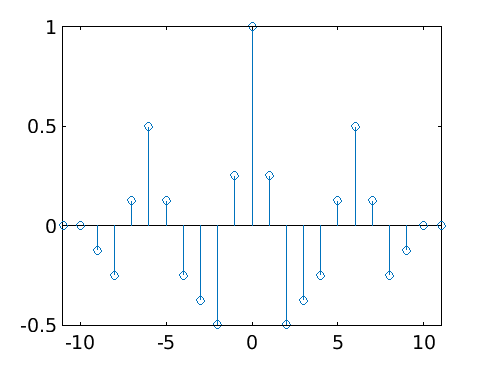

stem(lags, c)